# MATLAB Exercises for Hughes and Hase: Chapter 2

MATLAB activities to complement *Measurements and their Uncertainties*, Chapter 2, "Random errors in measurements." Section numbers in the book correspond to those listed below.

To use a module, first read the appropriate chapter in the textbook, and then read the module. These scripts have been saved in the Livescript version. To convert to a regular MATLAB script, just use **save as** and specify a .m filename extension. In the Livescript version, comments are shown with a blue or white background and MATLAB commands are shown with a grey background. When you get to a command, hit **Run Section** on your command panel to see the output. Most modules will include an exercise for you to practice what you have learned. After you are done, save the result in a pdf file for submission to Canvas. 

Author: J. S. Dodge, 2016 ©

## 2.1 Analysing distributions: some statistical ideas

Reproduce Fig. 2.1 using the `randn` and `histogram` functions, discussed in the notes for Ch. 1. Judging from Fig. 2.1(d), the distribution has mean $\bar{x} \approx 10$ and standard deviation $\sigma_x\approx 1$. Using a semi-colon (;) suppresses the output. You can remove it if you wish to see the output!

x0 = 10;
sigma = 1;

rng(1);                         % Initialize the RNG
x = x0 + sigma*randn(1000,1);   % Generate all 1000 points at once
disp(x(1:5))                    % Show the first 5

    9.3510
   11.1812
    9.2415
    8.8904
    9.1544



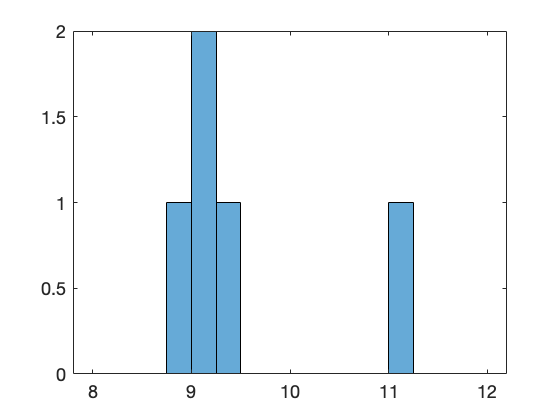

histogram(x(1:5),(8:0.25:12))   % The second argument here sets the bins -

                                %  each bin is 0.25 units wide, and they
                                %  span the range 8 to 12.

Note that the data are different from those shown in Hughes and Hase - they're random, after all. Now format the figure so that it is closer to what the book shows.

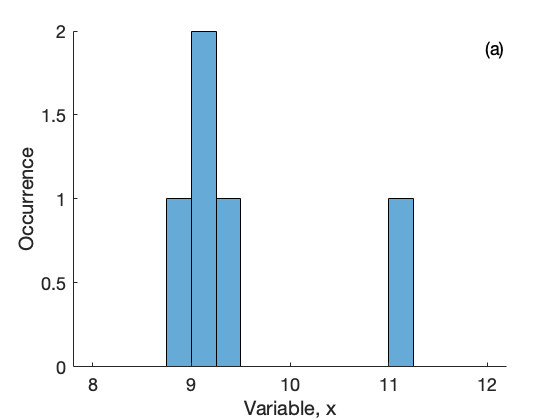

histogram(x(1:5),(8:0.25:12))
box off                         % Remove the box
xlabel('Variable, x')           % Label the x-axis
ylabel('Occurrence')            % Label the y-axis
text(0.95,0.95,'(a)',...        % Place the figure label '(a)' in the upper
    'Units','Normalized')       %  right corner; use '...' to continue the

                                %  command onto the next line. Set the text
                                %  units to 'Normalized' so that the label
                                %  position is placed with respect to the
                                %  graph axes.

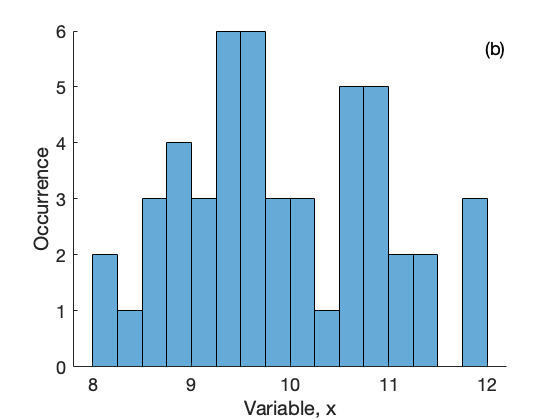

histogram(x(1:50),(8:0.25:12))
box off
xlabel('Variable, x')
ylabel('Occurrence')
text(0.95,0.95,'(b)',...
    'Units','Normalized')

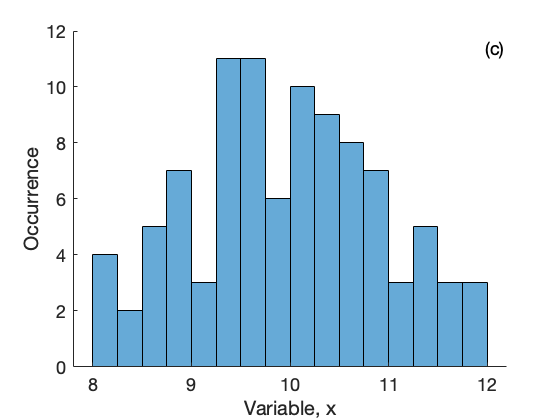

histogram(x(1:100),(8:0.25:12))
box off
xlabel('Variable, x')
ylabel('Occurrence')
text(0.95,0.95,'(c)',...
    'Units','Normalized')

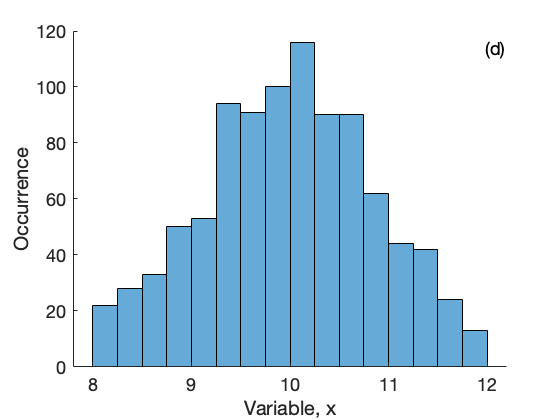

histogram(x,(8:0.25:12))
box off
xlabel('Variable, x')
ylabel('Occurrence')
text(0.95,0.95,'(d)',...
    'Units','Normalized')

## 2.2 The mean

The MATLAB function [`mean`](https://www.mathworks.com/help/matlab/ref/mean.html) computes the mean. Remember that we set the `x0 = 10` at the beginning.

xbar = mean(x);
disp(xbar)

    9.9867



Compare this with Eq. (2.1) in Hughes and Hase. It's always a good idea to check that functions are calculating what you think they are!

disp( sum(x)/length(x) )

    9.9867



## 2.3 The width of the distribution: estimating the precision

Consider the data in Table 2.1.

T = [10.0, 9.4, 9.8, 9.6, 10.5, 9.8, 10.3, 10.2, 10.4, 9.3];

Plot a histogram of the data. Let MATLAB choose the bins automatically.

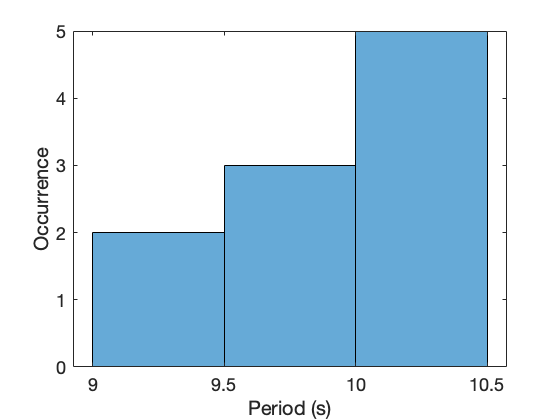

histogram(T)
xlabel('Period (s)')
ylabel('Occurrence')

Try using six bins.

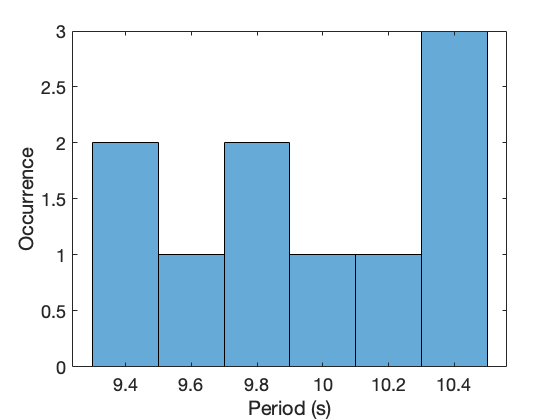

histogram(T,6)
xlabel('Period (s)')
ylabel('Occurrence')

Display the mean.

Tmean = mean(T);
disp(Tmean)

    9.9300



## 2.3.1 Rough-and-ready approach to estimating the width

To find the full range of the data, use the functions `max` and `min`.

Tmax = max(T);
Tmin = min(T);
dmax = abs(Tmean - [Tmin, Tmax]);

disp(dmax)

    0.6300    0.5700



The *total spread* of the data is (9.9 ± 0.6) s, as given in Hughes and Hase (note the significant figures). The 'rough-and-ready' method to estimating the spread gives:

sigmaRough = (2/3)*max(dmax);
disp(sigmaRough)

    0.4200



Compare this to the standard deviation, using the MATLAB function `std`.

sigma = std(T);
disp(sigma)

    0.4191



Check that this agrees with (2.3).

nT = length(T);
sigmaAlt = sqrt(sum((T-mean(T)).^2)/(nT-1));
disp(sigmaAlt)

    0.4191



The 'rough-and-ready' estimate is only useful for small sample sizes, and even then it's probably better just to calculate the standard deviation. The estimate gets worse as the sample size increases.

nSample = [3; 10; 30; 100; 300; 1000];
roughWidth = zeros(6,1);    % Initialize arrays
stdDev = zeros(6,1);

for iSample =  1:length(nSample)
    sample = randn(nSample(iSample),1);
    dMax = abs([max(sample),min(sample)] - mean(sample));
    roughWidth(iSample) = (2/3)*max(dMax);
    stdDev(iSample) = std(sample);
    disp(['N = ' num2str(nSample(iSample))])
    disp(['Rough method: ' num2str(roughWidth(iSample))])
    disp(['Standard dev.: ' num2str(stdDev(iSample))])
    disp(' ')
end

N = 3


Rough method: 0.26582


Standard dev.: 0.36953


N = 10


Rough method: 1.2398


Standard dev.: 1.0149


N = 30


Rough method: 1.7056


Standard dev.: 1.1786


N = 100


Rough method: 1.6742


Standard dev.: 0.98135


N = 300


Rough method: 2.1026


Standard dev.: 1.085


N = 1000


Rough method: 2.2925


Standard dev.: 1.0123


## 2.4 Continuous distributions

To reproduce Fig. 2.3, use the RNG to make 10,000 normally distributed numbers with the same mean and standard deviation as we used to reproduce Fig. 2.1.

x0 = 10;
sigma = 1;
nSample = 10000;

x = x0 + sigma*randn(nSample,1);   % Generate all 1000 points at once

The bins in Fig. 2.3(a) are 1.6 wide; the width decreases by a factor of two in each successive histogram. Use a loop to generate the four plots, using a character array to produce the different labels. To superpose the normal distribution on each plot, use the MATLAB function `linspace` to make an array `xVar`, and use (2.4); normalize to match the maximum of the histogram.

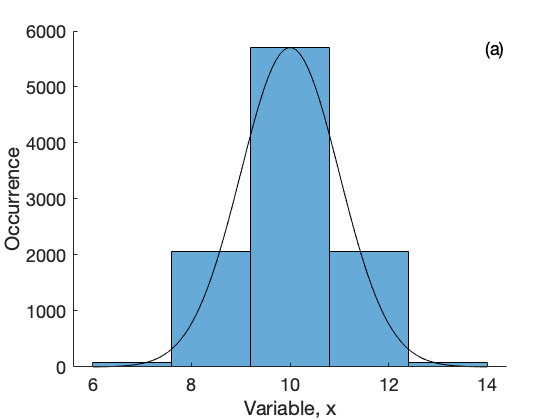

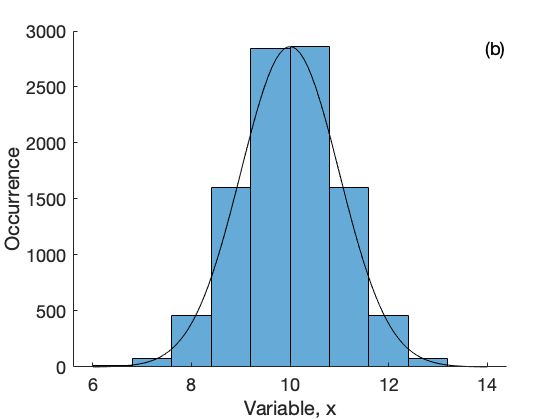

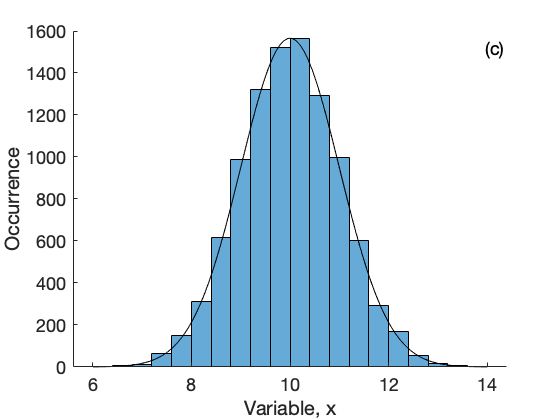

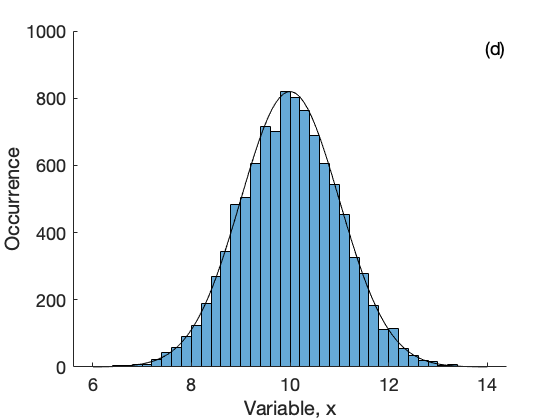

binStart = 6;
binEnd = 14;

xVar = linspace(binStart,binEnd);   % Default size of LINSPACE is [1,100]
f = (1/(sigma*sqrt(2*pi)))*exp(-((xVar - x0).^2/(2*sigma^2)));

binWidth = [1.6, 0.8, 0.4, 0.2];
labelArray = 'abcd';

for iPlot = 1:4
    
    figure;                 % Make a new figure for each panel
    h = histogram(x, (binStart : binWidth(iPlot) : binEnd));
    hMax = max(h.Values);   % h.Values contains the bin values
    box off
    
    hold on                 % Overlay next plot on current plot
                            % Plot the distribution as a black line
    plot(xVar,f*hMax*sqrt(2*pi)*sigma,'k-');
    
    xlabel('Variable, x')
    ylabel('Occurrence')
    label = ['(' labelArray(iPlot) ')'];
    text(0.95,0.95,label,...
        'Units','Normalized')
    
    hold off                % Return plot to default behaviour
end

## 2.5 The normal distribution

Reproduce Fig. 2.4. Define an [*anonymous function*](http://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) for (2.4) to simplify the computation of the three distributions. Note the LaTeX markup for the legend.

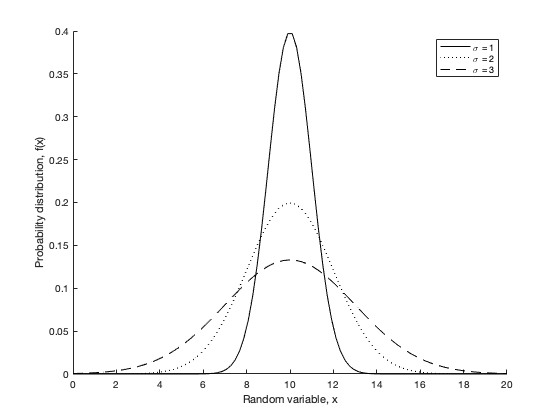

xVar = linspace(0,20);
f = @(x,mu,sigma) (1/(sigma*sqrt(2*pi)))*exp(-((x - mu).^2/(2*sigma^2)));

plot(xVar, f(xVar, 10, 1), 'k-', ...    % sigma = 1, solid black line
    xVar, f(xVar, 10, 2), 'k:', ...     % sigma = 2, dotted black line
    xVar, f(xVar, 10, 3), 'k--');       % sigma = 3, dashed black line

box off
xlabel('Random variable, x')
ylabel('Probability distribution, f(x)')
legend('\sigma = 1','\sigma = 2','\sigma = 3')

## 2.6 Sample and parent distribution

The default behaviour for [`std`](http://www.mathworks.com/help/matlab/ref/std.html) is to compute the sample standard deviation using (2.6), but it accepts an optional parameter that causes it to use (2.7) instead.

sigmaParent = std(T,1);
disp(sigmaParent)

    0.3976



Check that this agrees with (2.5).

sigmaParentAlt = sqrt(sum((T-mean(T)).^2)/nT);
disp(sigmaParentAlt)

    0.3976



The sample standard deviation from Sec. 2.3.2 is a bit bigger.

disp(std(T))

    0.4191



We can use the RNG to compare (2.5) and (2.6). Make a `5 x 1000` array of normally distributed random numbers, and compute both versions of the standard deviation for each of the 10000 columns (with $N = 5$).

data = randn(5,1000);
stdSample = std(data);
stdParent = std(data,1);

disp(stdSample(1:5))

    1.5844    1.5786    0.3323    0.8807    1.1664



disp(stdParent(1:5))

    1.4171    1.4120    0.2973    0.7877    1.0433



The parent distribution for the RNG has $\sigma = 1$. Both `stdSample` and `stdParent` are functions of five random numbers, so they are also random numbers. Comparing their averages over all 10,000 columns, we find that (2.5) underestimates the parent standard deviation when $N = 5$; the $N-1$ in (2.6) corrects for this.

disp(mean(stdSample))

    0.9376



disp(mean(stdParent))

    0.8387



For large data sets, though, the difference between `N` and `N-1` is negligible: consider `x` from Fig. 2.3.

disp(length(x))

       10000



disp(std(x))

    1.0034



disp(std(x,1))

    1.0033



## 2.7 The standard error

The sample standard deviation is an estimate of the distribution width. The standard *error* $\alpha$ estimates how well we know its mean value. If $N = 1$, then $\alpha = \sigma$, but our knowledge of $\mu$ improves with every new measurement, as Fig. 2.1 shows.

Return to the data in Table 2.1. For these ten measurements, we can estimate the mean of the parent distribution to be (9.9 ± 0.1) s.

disp(Tmean)

    9.9300




Tstderr = std(T)/sqrt(nT);
disp(Tstderr)

    0.1325



Confirm (2.7) for the `5 x 1000` random numbers in the array `data`: take the mean of each column, then find the standard deviation of the mean.

dataMean = mean(data);
dataMeanUnc = std(dataMean);
dataStd = std(data);
disp(dataMeanUnc)

    0.4291



disp(mean(dataStd)/sqrt(5))

    0.4193



## 2.7.1 The error in the error

For the data in Table 2.1, the fractional error in the error is 20% (to one significant figure).

disp(1/sqrt(2*nT - 2))

    0.2357



Confirm (2.8) for the `5 x 1000` random numbers in the array `data`: take the standard deviation of each column, then find the standard deviation of the standard deviation.

dataStdUnc = std(dataStd);
disp(dataStdUnc)

    0.3406



disp(mean(dataStd)/sqrt(2*5 - 2))

    0.3315



## Exercises

Please complete these exercises listed below in the worksheet. After you have finished the worksheet and the exercises, save the worksheet as a .pdf file and upload to Canvas.

## 1 - Exercise (2.3)

A measurement of 100 minutes will reduce the random error by a factor of 10.

## 2 - Exercise (2.5)

## **3 - Describing your data**

(a) Load the data set `DataBarlowProb2_6.txt`. 

(b) Show the data in a histogram, choosing a reasonable bin size.

(c) Calculate the mean and standard deviation of the data set, specifying which version of the standard deviation you have used.

(d) What is the uncertainty in any given data point?

(e) Generate a data set with the mean that you calculated in Part (c) and the same number of data points but a standard deviation that is twice as large, and add it to your histogram.